% Code for Theeta(s) = (N3*V(s) + N4*D2*D(s))/(D1*D2)
syms s kp ki kd;
clc,clearvars;
s = tf('s');
R = 0.3;
L = 0.45;
l = 0.8;
M = 16;
m = 80;
kT = 0.75;
kbemf = 0.75;
r_a = 1.5;
c1 = 0.1;
c2 = 0.1;
g = 9.81;
alpha = kT/r_a

alpha = 0.5000

beta = (kT*kbemf)/(R*r_a)

beta = 1.2500

kp = 12;
ki = 13;
kd = 18;
J = m*l^2 + M*L^2;
A = (M*g*L + m*g*l)/J;
B = beta/J;
C = alpha/J;
E = m*g/J;
F = c1/J;
G = alpha/(R*(M+m));
H = (beta/R + c2)/(M + m);
D1 = (s^2+F*s-A);
D2 = s+H;
x = (D1*D2)

x =
 
  s^3 + 0.04628 s^2 - 12.83 s - 0.5702
 
Continuous-time transfer function.
Model Properties


c =  [1 0.04628 -12.83 -0.5702];
x = roots(c)

x =     3.5810
   -3.5828
   -0.0444


%sX(s) transfer function using PID gains
p = G/(s+H);
q = kp+ki/s+kd*s;
x = p*q/(1+p*q)

x =
 
  0.3125 s^4 + 0.2222 s^3 + 0.235 s^2 + 0.01003 s
  -----------------------------------------------
  1.312 s^4 + 0.3111 s^3 + 0.2369 s^2 + 0.01003 s
 
Continuous-time transfer function.
Model Properties


% Here x is s*X(s) = x_dot(t)
pole(x)

ans =    0.0000 + 0.0000i
  -0.0963 + 0.4033i
  -0.0963 - 0.4033i
  -0.0444 + 0.0000i


% Since one of the poles is positive the system is unstable

N3 = (B*G-(s+H)*C);
N3/D2

ans =
 
  -0.009184 s - 9.567e-06
  -----------------------
        s + 0.04444
 
Continuous-time transfer function.
Model Properties


x = (D1*D2) + N3*(kp+ki/s+kd*s)

x =
 
  s^4 - 0.119 s^3 - 12.94 s^2 - 0.6897 s - 0.0001244
  --------------------------------------------------
                          s
 
Continuous-time transfer function.
Model Properties


N4 = E

N4 = 14.4159

x = ((D1*D2) - N3*(kp+ki/s+kd*s));
theeta = ((N4*D2)/(x))

theeta =
 
                 14.42 s^2 + 0.6407 s
  ---------------------------------------------------
  s^4 + 0.2116 s^3 - 12.72 s^2 - 0.4507 s + 0.0001244
 
Continuous-time transfer function.
Model Properties


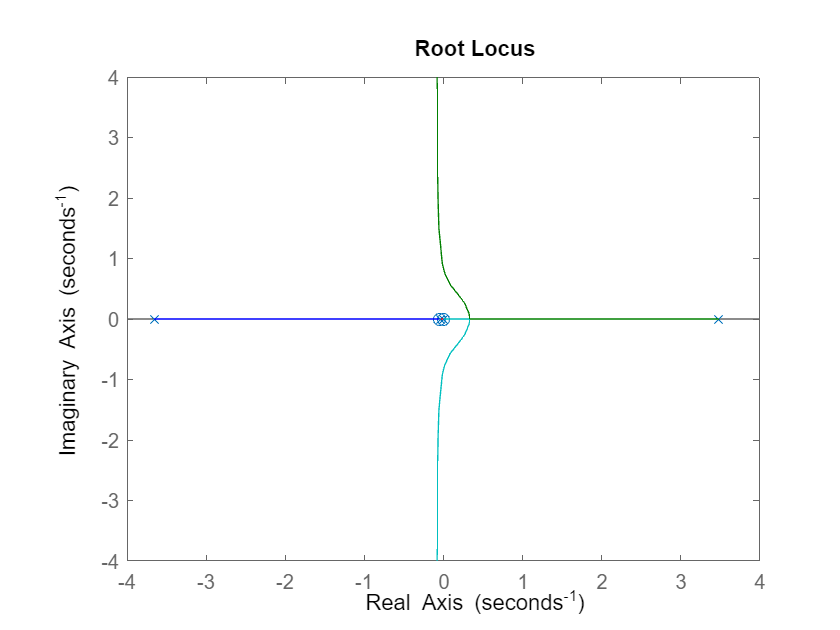

rlocus(theeta);